cbd_rats = {'Rat2', 'Rat5', 'Rat10', 'Rat11', 'Rat204', 'Rat205', 'Rat207', 'Rat209', 'Rat212', 'Rat214'};
veh_rats = {'Rat3', 'Rat4', 'Rat9', 'Rat201', 'Rat203', 'Rat206', 'Rat210', 'Rat211', 'Rat213'};
all_rats = [cbd_rats veh_rats];

pfc_dir_path = "D:\Dev\MATLAB\GenzelLab\data\PFC_all_animals";
pfc_dir_contents = dir(pfc_dir_path);
are_files = ~cell2mat({pfc_dir_contents.isdir});
pfc_dir_contents = {pfc_dir_contents(are_files).name};
pfc_files = strings(1,length(pfc_dir_contents));
for i = 1:length(pfc_dir_contents)
    pfc_files(i) = convertCharsToStrings(pfc_dir_contents{i});
end

checks = contains(pfc_files, "CH7") | ...
         contains(pfc_files, "CH8") | ...
         contains(pfc_files, "CH37");
checks = find(checks);
pfc_files = pfc_files(checks);

detections_dir_path = "D:\Dev\MATLAB\GenzelLab\sleep_oscil_tools\results\detections";
detections_dir_contents = dir(detections_dir_path);
are_files = ~cell2mat({detections_dir_contents.isdir});
detections_dir_contents = {detections_dir_contents(are_files).name};
detection_files = strings(1,length(detections_dir_contents));
for i = 1:length(detections_dir_contents)
    detection_files(i) = convertCharsToStrings(detections_dir_contents{i});
end

rats_phases = struct();
[c,d] = butter(3, [0.2/300 1/300]);
for i = 1:length(all_rats)
    rat = all_rats{i};
    rat_id = ['_' rat(4:end) '_'];
    pfc_file_index = find(contains(pfc_files, rat_id));
    pfc_file_path = fullfile(pfc_dir_path, pfc_files(pfc_file_index));
    pfc_sig = importdata(pfc_file_path);
    pfc_sig_filtered = filtfilt(c,d,pfc_sig);
    pfc_sig_hilbert = hilbert(pfc_sig_filtered);
    pfc_sig_phase_rad = angle(pfc_sig_hilbert);
    pfc_sig_phase_deg = mod(rad2deg(pfc_sig_phase_rad), 360);
    rats_phases.(rat) = pfc_sig_phase_deg;
end

rats_detections = struct();
for i = 1:length(all_rats)
    rat = all_rats{i};
    rat_id = rat(4:end);
    detections_file = ['detections' rat_id '.mat'];
    detections_file_path = fullfile(detections_dir_path, detections_file);
    detections = load(detections_file_path, 'grouped_oscil_table');
    detections_table = detections.grouped_oscil_table;
    rats_detections.(rat) = detections_table;
end

phases_per_detection_peak = struct();
for i = 1:length(all_rats)
    rat = all_rats{i};
    rat_phase = rats_phases.(rat);
    detections = rats_detections.(rat);
    total = detections.Peak;
    r = detections.Peak(find(cellfun(@(c) ismember(2,c) & length(c)==1, detections.Form)));
    sw = detections.Peak(find(cellfun(@(c) ismember(1,c) & length(c)==1, detections.Form)));
    swr = detections.Peak(find(cellfun(@length,detections.Form) == 2));
    cswr = detections.Peak(find(cellfun(@length,detections.Form) > 2));
    phases_per_detection_peak.('Total').(rat) = rat_phase(uint64(total));
    phases_per_detection_peak.('Ripples').(rat) = rat_phase(uint64(r));
    phases_per_detection_peak.('SharpWaves').(rat) = rat_phase(uint64(sw));
    phases_per_detection_peak.('SharpWaveRipples').(rat) = rat_phase(uint64(swr));
    phases_per_detection_peak.('ComplexSharpWaveRipples').(rat) = rat_phase(uint64(cswr));
end

phases_per_detection_mean = struct();
for i = 1:length(all_rats)
    rat = all_rats{i};
    rat_phase = rats_phases.(rat);
    detections = rats_detections.(rat);
    total = [detections.Start detections.End];
    r_indexes = find(cellfun(@(c) ismember(2,c) & length(c)==1, detections.Form));
    sw_indexes = find(cellfun(@(c) ismember(1,c) & length(c)==1, detections.Form));
    swr_indexes = find(cellfun(@length,detections.Form) == 2);
    cswr_indexes = find(cellfun(@length,detections.Form) > 2);
    
    for j = 1:length(total)
        detection_start = uint64(total(j,1));
        detection_end = uint64(total(j,2));
        detection_phase = rat_phase(detection_start:detection_end);
        detection_mean_phase = mean(detection_phase);
        phases_per_detection_mean.('Total').(rat) = detection_mean_phase;
        if ismember(j, r_indexes)
            phases_per_detection_mean.('Ripples').(rat) = detection_mean_phase;
        elseif ismember(j, sw_indexes)
            phases_per_detection_mean.('SharpWaves').(rat) = detection_mean_phase;
        elseif ismember(j, swr_indexes)
            phases_per_detection_mean.('SharpWaveRipples').(rat) = detection_mean_phase;
        elseif ismember(j, cswr_indexes)
            phases_per_detection_mean.('ComplexSharpWaveRipples').(rat) = detection_mean_phase;
        end
    end
end

# Rat 203

whichrat = 'Rat212';

## Total

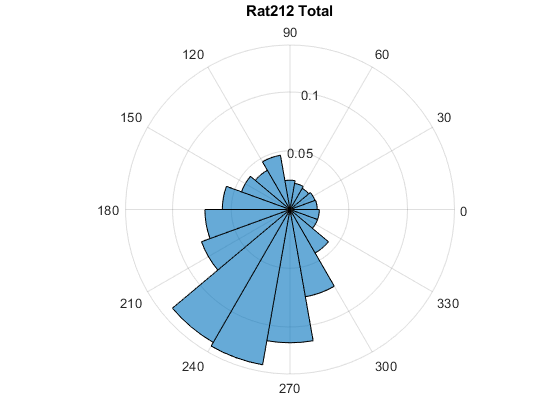

count = phases_per_detection_peak.('Total').(whichrat);
    
figure
polarhistogram(deg2rad(count),18,'Normalization','probability')
title([whichrat ' Total'])

## SharpWaves

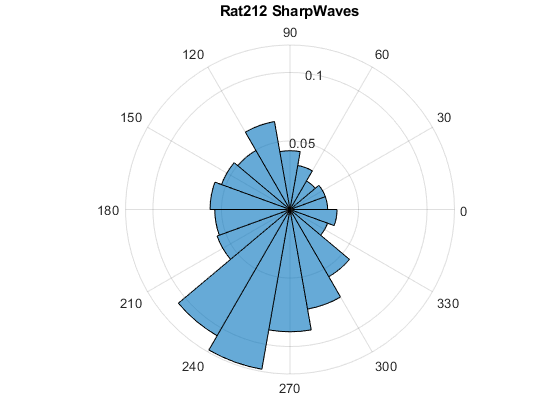

count_sw = phases_per_detection_peak.('SharpWaves').(whichrat);
   
figure
polarhistogram(deg2rad(count_sw),18,'Normalization','probability')
title([whichrat ' SharpWaves'])

## Ripples

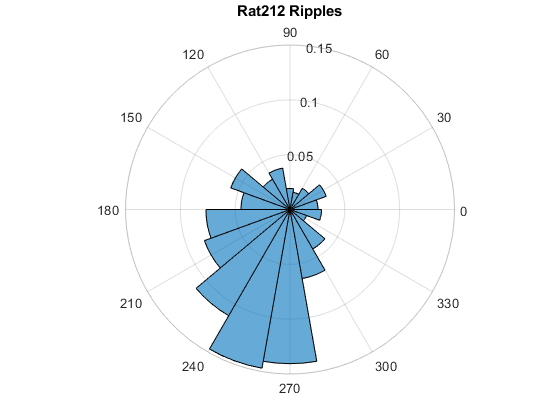

count_r = phases_per_detection_peak.('Ripples').(whichrat);
    
figure
polarhistogram(deg2rad(count_r),18,'Normalization','probability')
title([whichrat ' Ripples'])

## SharpWaveRipples

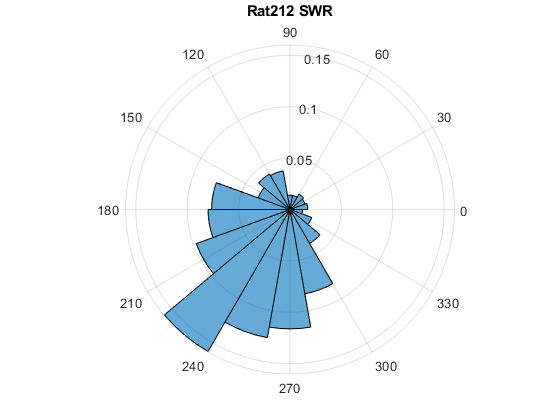

count_swr = phases_per_detection_peak.('SharpWaveRipples').(whichrat);
    
figure
polarhistogram(deg2rad(count_swr),18,'Normalization','probability')
title([whichrat ' SWR'])

## ComplexSharpWaveRipples

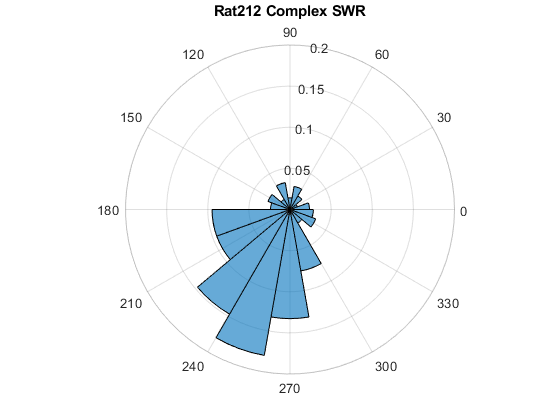

count_cswr = phases_per_detection_peak.('ComplexSharpWaveRipples').(whichrat);
    
figure
polarhistogram(deg2rad(count_cswr),18,'Normalization','probability')
title([whichrat ' Complex SWR'])

## 4 in 1

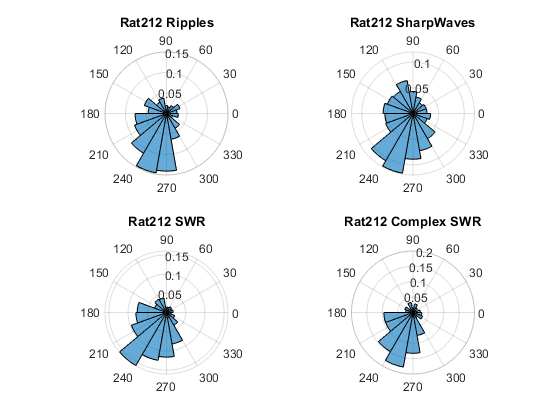

count_r = phases_per_detection_peak.('Ripples').(whichrat);
count_sw = phases_per_detection_peak.('SharpWaves').(whichrat);
count_swr = phases_per_detection_peak.('SharpWaveRipples').(whichrat);
count_cswr = phases_per_detection_peak.('ComplexSharpWaveRipples').(whichrat);

figure
subplot(2,2,1);
polarhistogram(deg2rad(count_r),18,'Normalization','probability')
title([whichrat ' Ripples'])
subplot(2,2,2);
polarhistogram(deg2rad(count_sw),18,'Normalization','probability')
title([whichrat ' SharpWaves'])
subplot(2,2,3);
polarhistogram(deg2rad(count_swr),18,'Normalization','probability')
title([whichrat ' SWR'])
subplot(2,2,4);
polarhistogram(deg2rad(count_cswr),18,'Normalization','probability')
title([whichrat ' Complex SWR'])

# All Rats

## Total

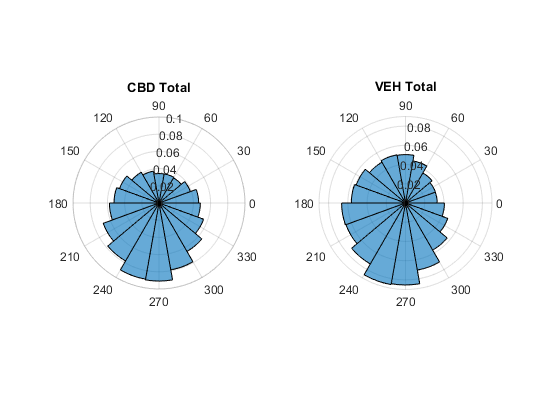

cbd = [];
for i = 1:length(cbd_rats)
    rat = cbd_rats{i};
    cbd = [cbd; phases_per_detection_peak.('Total').(rat)];
end
veh = [];
for i = 1:length(veh_rats)
    rat = veh_rats{i};
    veh = [veh; phases_per_detection_peak.('Total').(rat)];
end
figure
subplot(1,2,1);
polarhistogram(deg2rad(cbd),18,'Normalization','probability')
title('CBD Total')
subplot(1,2,2);
polarhistogram(deg2rad(veh),18,'Normalization','probability')
title('VEH Total')

## SharpWaves

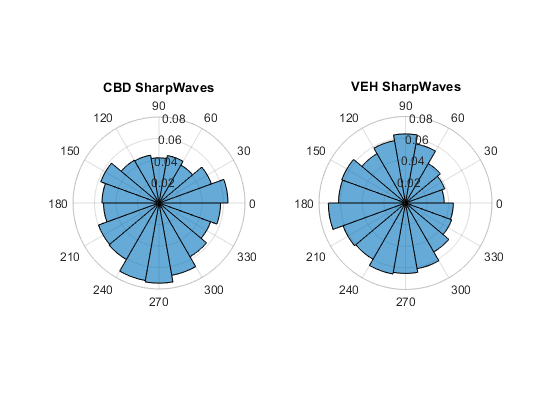

cbd = [];
for i = 1:length(cbd_rats)
    rat = cbd_rats{i};
    cbd = [cbd; phases_per_detection_peak.('SharpWaves').(rat)];
end
veh = [];
for i = 1:length(veh_rats)
    rat = veh_rats{i};
    veh = [veh; phases_per_detection_peak.('SharpWaves').(rat)];
end
figure
subplot(1,2,1);
polarhistogram(deg2rad(cbd),18,'Normalization','probability')
title('CBD SharpWaves')
subplot(1,2,2);
polarhistogram(deg2rad(veh),18,'Normalization','probability')
title('VEH SharpWaves')

## Ripples

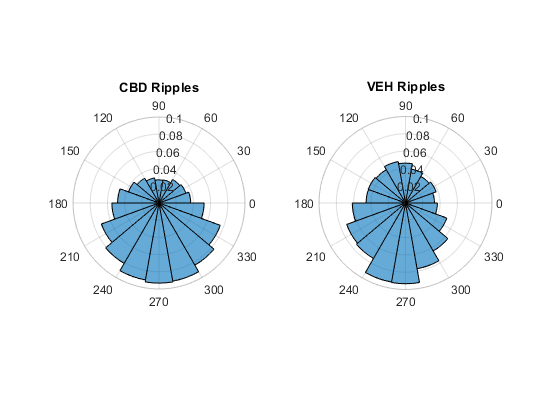

cbd = [];
for i = 1:length(cbd_rats)
    rat = cbd_rats{i};
    cbd = [cbd; phases_per_detection_peak.('Ripples').(rat)];
end
veh = [];
for i = 1:length(veh_rats)
    rat = veh_rats{i};
    veh = [veh; phases_per_detection_peak.('Ripples').(rat)];
end
figure
subplot(1,2,1);
polarhistogram(deg2rad(cbd),18,'Normalization','probability')
title('CBD Ripples')
subplot(1,2,2);
polarhistogram(deg2rad(veh),18,'Normalization','probability')
title('VEH Ripples')

## SharpWaveRipples

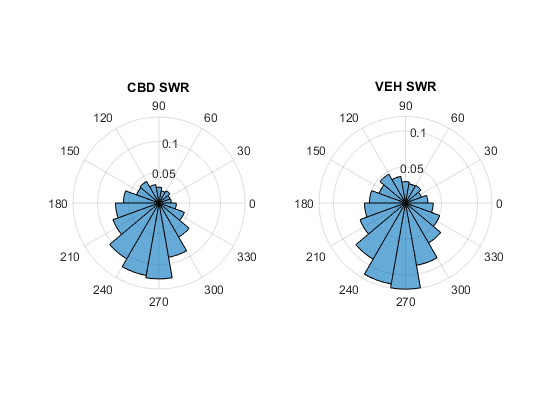

cbd = [];
for i = 1:length(cbd_rats)
    rat = cbd_rats{i};
    cbd = [cbd; phases_per_detection_peak.('SharpWaveRipples').(rat)];
end
veh = [];
for i = 1:length(veh_rats)
    rat = veh_rats{i};
    veh = [veh; phases_per_detection_peak.('SharpWaveRipples').(rat)];
end
figure
subplot(1,2,1);
polarhistogram(deg2rad(cbd),18,'Normalization','probability')
title('CBD SWR')
subplot(1,2,2);
polarhistogram(deg2rad(veh),18,'Normalization','probability')
title('VEH SWR')

## ComplexSharpWaveRipples

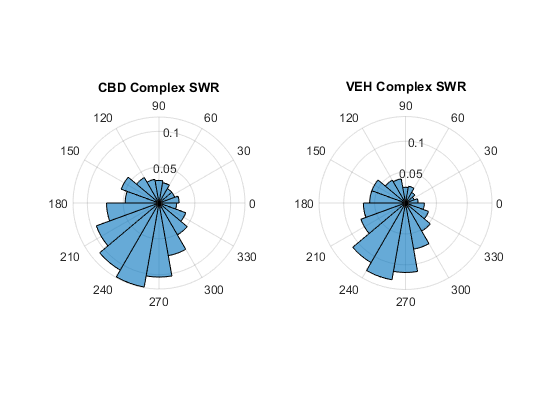

cbd = [];
for i = 1:length(cbd_rats)
    rat = cbd_rats{i};
    cbd = [cbd; phases_per_detection_peak.('ComplexSharpWaveRipples').(rat)];
end
veh = [];
for i = 1:length(veh_rats)
    rat = veh_rats{i};
    veh = [veh; phases_per_detection_peak.('ComplexSharpWaveRipples').(rat)];
end
figure
subplot(1,2,1);
polarhistogram(deg2rad(cbd),18,'Normalization','probability')
title('CBD Complex SWR')
subplot(1,2,2);
polarhistogram(deg2rad(veh),18,'Normalization','probability')
title('VEH Complex SWR')